# Path Following for a Differential Drive Robot

This example demonstrates how to control a robot to follow a desired path using a Robot Simulator. The example uses the Pure Pursuit path following controller to drive a simulated robot along a predetermined path. A desired path is a set of waypoints defined explicitly or computed using a path planner (refer to [Path Planning in Environments of Different Complexity](docid:robotics_examples.mw_04f9e096-7491-4efd-8380-9d7e178f95b6)). The Pure Pursuit path following controller for a simulated differential drive robot is created and computes the control commands to follow a given path. The computed control commands are used to drive the simulated robot along the desired trajectory to follow the desired path based on the Pure Pursuit controller.

Note: Starting in R2016b, instead of using the step method to perform the operation defined by the System object™, you can call the object with arguments, as if it were a function. For example, `y = step(obj,x)` and `y = obj(x)` perform equivalent operations.

## Define Waypoints

Define a set of waypoints for the desired path for the robot

close all, clear
% path = [2.00    1.00;
%     1.25    1.75;
%     5.25    8.25;
%     7.25    8.75;
%     11.75   10.75;
%     12.00   10.00];


Set the current location and the goal location of the robot as defined by the path.

robotCurrentLocation = [0,0];
% robotGoal = path(end,:);
rosshutdown

Shutting down global node /matlab_global_node_58294 with NodeURI http://localhost:46546/


rosinit

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
The value of the ROS_HOSTNAME environment variable, localhost, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_03637 with NodeURI http://localhost:36457/


possub = rossubscriber('/position','geometry_msgs/Point');
odomsub = rossubscriber('/odom','nav_msgs/Odometry');
[cmdpub,cmdmsg] = rospublisher('/cmd_vel','geometry_msgs/Twist');

Assume an initial robot orientation (the robot orientation is the angle between the robot heading and the positive X-axis, measured counterclockwise).

initialOrientation = 0;

Define the current pose for the robot [x y theta]

robotCurrentPose = [robotCurrentLocation initialOrientation];

## Initialize the Robot Simulator

A simple robot simulator is used in this example that updates and returns the pose of the differential drive robot for given control inputs. An external simulator or a physical robot will require a localization mechanism to provide an updated pose of the robot.

Initialize the robot simulator and assign an initial pose. The simulated robot has kinematic equations for the motion of a two-wheeled differential drive robot. The inputs to this simulated robot are linear and angular velocities. It also has plotting capabilities to display the robot's current location and draw the trajectory of the robot.

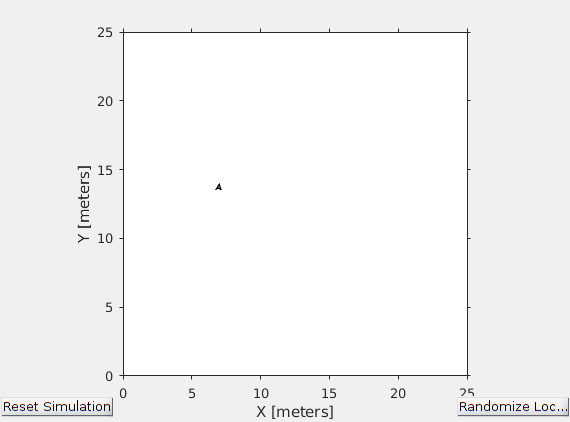

robotRadius = 0.26;
robot = ExampleHelperRobotSimulator('emptyMap',2);
robot.enableLaser(false);
robot.setRobotSize(robotRadius);

% robot.showTrajectory(true);
% robot.setRobotPose(robotCurrentPose);


Visualize the desired path

% plot(path(:,1), path(:,2),'k--d')
% xlim([0 13])
% ylim([0 13])

## Define the Path Following Controller

Based on the path defined above and a robot motion model, you need a path following controller to drive the robot along the path. Create the path following controller using the [`robotics.PurePursuit`](docid:robotics_ref.buoofp1-1) object.

controller = robotics.PurePursuit;

Use the path defined above to set the desired waypoints for the controller

% controller.Waypoints = path;

Set the path following controller parameters. The desired linear velocity is set to 0.3 meters/second for this example.

controller.DesiredLinearVelocity = 0.5;

The maximum angular velocity acts as a saturation limit for rotational velocity, which is set at 2 radians/second for this example.

controller.MaxAngularVelocity = 1;

As a general rule, the lookahead distance should be larger than the desired linear velocity for a smooth path. The robot might cut corners when the lookahead distance is large. In contrast, a small lookahead distance can result in an unstable path following behavior. A value of 0.5 m was chosen for this example.

controller.LookaheadDistance = 0.5;

## Using the Path Following Controller, Drive the Robot over the Desired Waypoints

The path following controller provides input control signals for the robot, which the robot uses to drive itself along the desired path.

Define a goal radius, which is the desired distance threshold between the robot's final location and the goal location. Once the robot is within this distance from the goal, it will stop. Also, you compute the current distance between the robot location and the goal location. This distance is continuously checked against the goal radius and the robot stops when this distance is less than the goal radius.

Note that too small value of the goal radius may cause the robot to miss the goal, which may result in an unexpected behavior near the goal.

goalRadius = 0.1;

while 1
    posdata = receive(possub);
    robotGoal = [posdata.X, posdata.Y];
    distanceToGoal = norm(robotCurrentLocation - robotGoal); %(Euclidean norm)

The [`controller`](docid:robotics_ref.buoofp1-1) object computes control commands for the robot. Drive the robot using these control commands until it reaches within the goal radius. If you are using an external simulator or a physical robot, then the controller outputs should be applied to the robot and a localization system may be required to update the pose of the robot. The controller runs at 10 Hz.

Error using coder.internal.assert (line 33)
The property 'Waypoints' is empty. Assign waypoints before using the step function.

Error in coder.internal.errorIf (line 7)
coder.internal.assert(~cond, msgID, varargin{:});

Error in 

    controlRate = robotics.Rate(10);
    while( distanceToGoal > goalRadius )
        odomdata = receive(odomsub);
        posedata = [odomdata.Pose.Pose.Position.X, odomdata.Pose.Pose.Position.Y, odomdata.Pose.Pose.Orientation.W];
        % Compute the controller outputs, i.e., the inputs to the robot
        [v, omega] = controller(posedata);
        
        % Simulate the robot using the controller outputs.        
        %     drive(robot, v, omega);
        cmdmsg.Linear.X = v;
        cmdmsg.Linear.Y = 0;
        cmdmsg.Linear.Z = 0;
        cmdmsg.Angular.X = 0;
        cmdmsg.Angular.Y = 0;
        cmdmsg.Angular.Z = omega;
        send(cmdpub,cmdmsg);
        
        % Extract current location information ([X,Y]) from the current pose of the robot
        robotCurrentPose = posedata; % robotCurrentPose(X,Y,W)
        
        
        % Re-compute the distance to the goal
        distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal);
        
        waitfor(controlRate);
        
    end

end